# Script to initialise parameters for pendulum model

This script needs to be executed before running corresponding simulink models

## Plant model

### Set parameters of the plant model

g = 9.81; %m/s^2, gravitational constant

m = 5;    %kg, mass
l = 0.4;  %m, lengt h
I =m*l^2/3; %moment of inertia;

Set damping value which defines whether poles of Po are real or complex conjugate:

- 10 - real poles, 

- 2.5 or 0.5 - complex conjugate poles

fprintf('Damping ')

Damping 

c =10  %Nm/rad

c = 10

### Implement model as linear transfer function

wn=sqrt(m*g*l/(2*I));  % natural frequency
xi=c/(2*I*wn);         % damping coefficient


calculate the linear plant transfer function

Po = tf(1/I, [1 2*xi*wn wn^2])

Po =
 
          3.75
  --------------------
  s^2 + 37.5 s + 36.79
 
Continuous-time transfer function.



zpk(Po)

ans =
 
         3.75
  -------------------
  (s+36.49) (s+1.008)
 
Continuous-time zero/pole/gain model.



calculate poles of the Po (there are no zeros)

fprintf('Roots of Po:')

Roots of Po:

roots(Po.Denominator{1})

ans =   -36.4919
   -1.0081


## Controller

### Select controller gain and time constants

Suggested combinations: 

- Proportional controller:  K=100 or 1000; Ti=inf; Td=0;

- PID controller 

- K=100; Ti=10; Td=0.01;

- K=1000; Ti=1; Td=0.01;

- K=100; Ti=.1; Td=0.1;

fprintf('Controller parameters:')

Controller parameters:

K= 100 % overall gain 

K = 100

Ti=1 % time constant for integral part. inf=disabled

Ti = 1

Td=0.01 % time constant for derivative part. 0=disabled

Td = 0.0100

taud=1e-3;              % time constant for realisable derivative

#### Implement controller components

Cp=zpk([],[],K);   % proportional
Ci=tf(K/Ti,[1 0]); % integral
Cd=K*Td*tf([1 0],[1]); % differential
Cdd=K*Td*tf([1 0],[taud 1]); % realisable differential

#### Combine components for ideal controller

C=Cp+Ci+Cd;  % ideal controller
L=C*Po;


#### Combine components for realisable controller (using Cdd instead of Cd)

C1=Cp+Ci+Cdd; % realiseable controller
L1=C1*Po;

### Bode plot

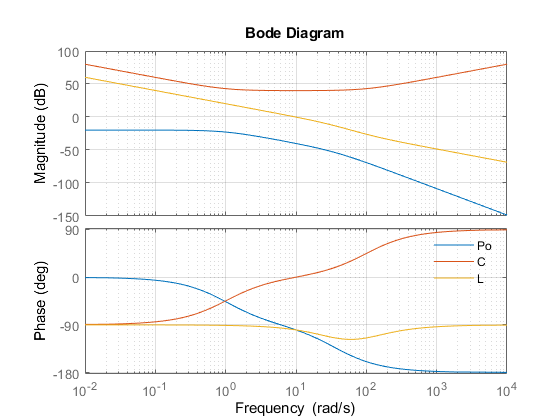

figure
bode(Po,C,L); 
hl=legend('Po', 'C', 'L');
set(hl,'box','off')
grid on

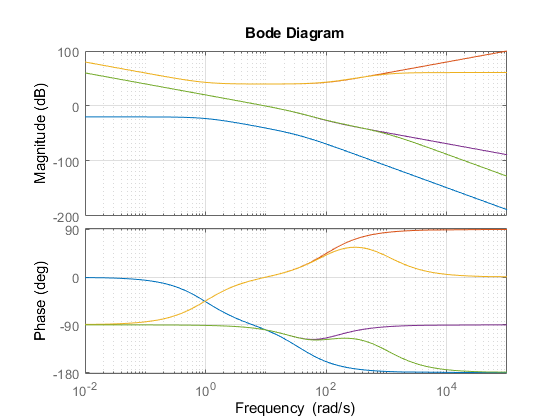


figure
bode(Po,C,C1,L,L1); 
%hl=legend('$P_o$', '$C$', '$C_{realisable}$', '$L$', '$L_{realisable}$','Interpreter','latex');
%set(hl,'box','off')
grid on